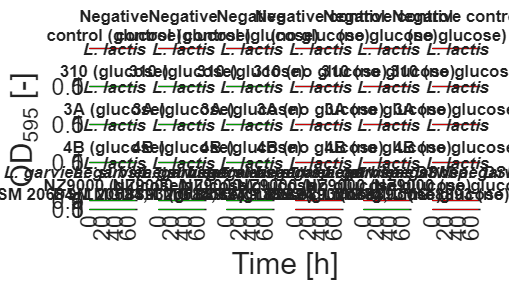

function out = split_title_halfword(s, maxLen)
    % Split long titles near midpoint using " " or "-" as breakpoints.
    % If split occurs at '-', the hyphen is kept at the end of line 1.

    s = char(s);
    n = length(s);

    if n <= maxLen
        out = s;
        return;
    end

    % Ideal center
    mid = ceil(n/2);

    % Find split positions (space or hyphen)
    splitPositions = regexp(s, '[ -]');

    if isempty(splitPositions)
        out = s;
        return;
    end

    % Choose split location closest to midpoint
    [~, idx] = min(abs(splitPositions - mid));
    splitPos = splitPositions(idx);

    % Hyphen → keep it
    if s(splitPos) == '-'
        firstLine  = s(1:splitPos);
        secondLine = s(splitPos+1:end);
    else
        % Space → remove the space
        firstLine  = s(1:splitPos-1);
        secondLine = s(splitPos+1:end);
    end

    % Clean up whitespace
    firstLine  = strtrim(firstLine);
    secondLine = strtrim(secondLine);

    out = sprintf('%s\n%s', firstLine, secondLine);
end

%% LOAD DATA
T = readtable("D:\growth_experiments_results\results_lactococcus\ZMB1\ZMB1+-glucose.xlsx", "ReadVariableNames", false);

time_sec = T{:,2};
time_min = time_sec / 60;
time_hr  = time_min / 60;

data = T{:,3:38};   % 36 wells

%% GLOBAL MAX OD FOR Y-LIMIT
global_max_od = max(data(:));
y_upper = global_max_od * 1.1;

%% WELL MAP
well_ids = {
    'A01','A02','A03','A04','A05','A06',...
    'B01','B02','B03','B04','B05','B06',...
    'C01','C02','C03','C04','C05','C06',...
    'D01','D02','D03','D04','D05','D06',...
    'E01','E02','E03','E04','E05','E06',...
    'F01','F02','F03','F04','F05','F06'
};

wells = struct( ...
    'A01','Negative control (glucose)', ...
    'A02','Negative control (glucose)', ...
    'A03','Negative control (glucose)', ...
    'A04','Negative control (no glucose)', ...
    'A05','Negative control (no glucose)', ...
    'A06','Negative control (no glucose)', ...
    'B01','\itL. lactis \rm\bf310 (glucose)', ...
    'B02','\itL. lactis \rm\bf310 (glucose)', ...
    'B03','\itL. lactis \rm\bf310 (glucose)', ...
    'B04','\itL. lactis \rm\bf310 (no glucose)', ...
    'B05','\itL. lactis \rm\bf310 (no glucose)', ...
    'B06','\itL. lactis \rm\bf310 (no glucose)', ...
    'C01','\itL. lactis \rm\bf3A (glucose)', ...
    'C02','\itL. lactis \rm\bf3A (glucose)', ...
    'C03','\itL. lactis \rm\bf3A (glucose)', ...
    'C04','\itL. lactis \rm\bf3A (no glucose)', ...
    'C05','\itL. lactis \rm\bf3A (no glucose)', ...
    'C06','\itL. lactis \rm\bf3A (no glucose)', ...
    'D01','\itL. lactis \rm\bf4B (glucose)', ...
    'D02','\itL. lactis \rm\bf4B (glucose)', ...
    'D03','\itL. lactis \rm\bf4B (glucose)', ...
    'D04','\itL. lactis \rm\bf4B (no glucose)', ...
    'D05','\itL. lactis \rm\bf4B (no glucose)', ...
    'D06','\itL. lactis \rm\bf4B (no glucose)', ...
    'E01','\itL. lactis \rm\bfNZ9000 (glucose)', ...
    'E02','\itL. lactis \rm\bfNZ9000 (glucose)', ...
    'E03','\itL. lactis \rm\bfNZ9000 (glucose)', ...
    'E04','\itL. lactis \rm\bfNZ9000 (no glucose)', ...
    'E05','\itL. lactis \rm\bfNZ9000 (no glucose)', ...
    'E06','\itL. lactis \rm\bfNZ9000 (no glucose)', ...
    'F01','\itL. garvieae subsp. garvieae DSM 20684, LMG 8893 \rm\bf(glucose)', ...
    'F02','\itL. garvieae subsp. garvieae DSM 20684, LMG 8893 \rm\bf(glucose)', ...
    'F03','\itL. garvieae subsp. garvieae DSM 20684, LMG 8893 \rm\bf(glucose)', ...
    'F04','\itL. garvieae subsp. garvieae DSM 20684, LMG 8893 \rm\bf(no glucose)', ...
    'F05','\itL. garvieae subsp. garvieae DSM 20684, LMG 8893 \rm\bf(no glucose)', ...
    'F06','\itL. garvieae subsp. garvieae DSM 20684, LMG 8893 \rm\bf(no glucose)' ...
);

%% PARAMETERS
numRows = 6;
numCols = 6;

ref_curve = data(:,1);
ref_max = max(ref_curve);

t_first = min(time_hr);
t_last  = max(time_hr);

x_min = max(0, floor(t_first - 4));
x_max = ceil(t_last + 4);

forced_ticks = [20 40 60];

%% FULL SCREEN FIGURE
figure('Units','normalized','Position',[0 0 1 1]);

%% PLOT
t = tiledlayout(numRows, numCols);
t.Padding = 'compact';
t.TileSpacing = 'compact';

for i = 1:36
    ax = nexttile;

    % Thicker axes + ticks (optional)
    ax.LineWidth = 1.2;

    curve = data(:,i);

    % Fold-change color
    curr_max = max(curve);
    fold_change = curr_max / ref_max;
    plotColor = [0 0.6 0] * (fold_change >= 3) + ...
                [0.8 0 0] * (fold_change < 3);

    plot(time_hr, curve, 'Color', plotColor, 'LineWidth', 1.4);
    ylim([0 y_upper]);
    xlim([x_min x_max]);

    % TITLE (left-most of each triplicate)
    
    rawTitle = wells.(well_ids{i});
    niceTitle = split_title_halfword(rawTitle, 20);
    title(niceTitle, "FontSize", 10);
    
    % AXIS FORMATTING
    row = ceil(i / numCols);
    col = i - (row-1)*numCols;

    xt = unique([ax.XTick forced_ticks]);
    xt(xt == 50) = [];
    xt = xt(xt >= x_min & xt <= x_max);
    ax.XTick = xt;

    yt = unique([ax.YTick 0.5]);
    ax.YTick = yt;

    fs = 14;

    if col ~= 1
        ax.YTickLabel = [];
    else
        ax.YAxis.FontSize = fs;
    end

    if row ~= numRows
        ax.XTickLabel = [];
    else
        ax.XAxis.FontSize = fs;
    end
end

xlabel(t, "Time [h]", "FontSize", 18);
ylabel(t, "OD_{595} [-]", "FontSize", 18);